### Linear Algebra and Programming Skills

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Example MATLAB Programs

This live script contains some example programs to give you an idea of how we can use Python to perform calculations and plot images.

## Calculating a root of a polynomial function using Newton's method

[Newton's method](https://en.wikipedia.org/wiki/Newton%27s_method) is a numerical algorithm for finding the root of a polynomial function. Let $f$ be a polynomial function which has a root at $x$ such that $f(x)=0$ then $x$ can be approximated using the iterative scheme

$x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)}$,

where $f'$ is the derviative of $f$. The scheme is started with an initial guess value $x_0$.

For example consider the function $f(x) = x^2 - 4x - 7$. Here $f'(x) = 2x - 4$ so Newton's method for this function is

$x_{n+1} = x_n - \frac{x_n^2 - 4x_n - 7}{2x_n - 4}$,

and using a starting value of $x_0=5$ we have


$$x_0=5, \\
x_1=5 - \frac{5^2 - 4(5)-7}{2(5)-4} = 5.333333, \\
x_2 = 5.333333 - \frac{5.333333^2 - 4(5.333333) - 4}{2(5.333333)-4} = 5.316667, \\
x_3=5.316667 - \frac{5.316667^2 - 4(5.316667) - 7}{2(5.316667)-4} = 5.316625, \\
x_4 = 5.316625 - \frac{5.316625^2 - 4(5.316625)-7}{2(5.316625)-4} = 5.316625.$$


The difference in the values obtained in the last two iterations agree to six decimal places so we know this is close to the actual root. When using numerical methods, we use a **convergence tolerance** $tol$ which is some small number and we cease iterations when $|x_{n+1} - x_n| < tol$. The smaller the value of $tol$ the more accurate our approximation is but will require more iterations, and therefore computational effort, to calculate.

The program below uses Newton's method to find this root. Note that using functions to calculate $f(x)$ and $f\prime (x)$ means that we can easily adapt it to find the roots of other polynomial functions.

% Define function and its derivative (using inline function definitions)
f = @(x) x .^ 2 - 4 * x - 7;
df = @(x) 2 * x - 4;

% Define parameters
maxiter = 100;            % maximum iteration limit
tol = 5e-6;               % convergence tolerange
x = zeros(maxiter+1, 1);  % array containing the estimates of the root
x(1) = 5;                 % starting value

% Iteration loop
for n = 1 : maxiter
    
    % Calculate new value of x using Newton's method
    x(n+1) = x(n) - f(x(n)) / df(x(n));
    
    % Check for convergence
    if abs(x(n+1) - x(n)) < tol
        break
    end
    
end

% Trim x array
x = x(1:n+1);

% Print a table containing the estimates of the root
table = '  n     x_n\n--------------\n';
for i = 1 : n + 1
    table = [ table, sprintf('%3i %10.6f\n', i - 1, x(i)) ];
end
fprintf(table);

  n     x_n
--------------
  0   5.000000
  1   5.333333
  2   5.316667
  3   5.316625
  4   5.316625


We can plot the function to check whether $f(x)=0$.

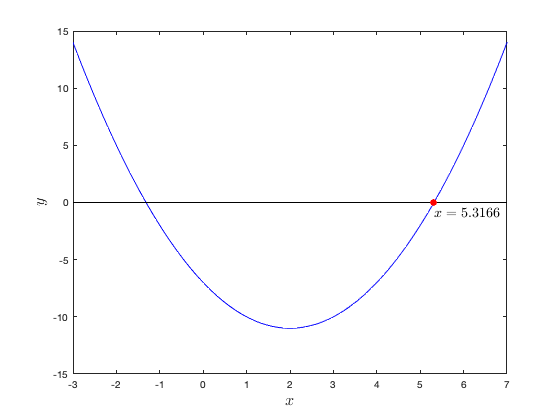

% Plot function and root
xmin = -3; xmax = 7;
x1 = linspace(xmin, xmax, 100);

plot(x1, f(x1), 'b-')
hold on
plot([xmin, xmax], [0, 0], 'k-')
plot(x(n+1), 0, 'ro', 'MarkerFaceColor', 'r')
hold off

axis([xmin, xmax, -15, 15])
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 16)
text(x(n+1), -1, sprintf('$x=%1.4f$', x(n+1)),  'Interpreter', 'latex', 'FontSize', 14)

## Calculating an inverse matrix using Gauss-Jordan elimination

One method of calculating the inverse of a matrix $A$ is to form an augmented matrix $(A|I)$ and use [Gauss-Jordan elimination](https://en.wikipedia.org/wiki/Gaussian_elimination) to row reduce the left-hand matrix to reduced row echelon form (i.e., the left-hand matrix becomes the identity matrix). The right-hand matrix is now $A^{-1}$.

For example, consider $A = \left( 
\matrix{ 1 & 2 \cr 3 & 4 }
\right)$.


$$\pmatrix{1 & 2 & 1 & 0 \cr 3 & 4 & 0 & 1} \longrightarrow
\pmatrix{3 & 4& 0 & 1 \cr 1 & 2 & 1 & 0} \longrightarrow
\pmatrix{1 & 4/3 & 0 & 1/3 \cr 1 & 2 & 1 & 0}  \longrightarrow
\pmatrix{1 & 4/3 & 0 & 1/3 \cr 0 & 2/3 & 1 & -1/3} \longrightarrow \\
\pmatrix{1 & 4/3 & 0 & 1/3 \cr 0 & 1 & 3/2 & -1/2} \longrightarrow
\pmatrix{1 & 0 & -2 &  1 \cr 0 & 1 & 3/2 & -1/2}$$


So $A^{-1}=\pmatrix{-2&1\cr 3/2 &-1/2}$. We can check this using $A^{-1}A=I$

$\pmatrix{-2&1\cr 3/2 &-1/2}
\pmatrix{1&2\cr 3&4}=
\pmatrix{1&0\cr 0&1}$.

The program below uses Gauss-Jordan elimination to calculate the inverse of a square matrix. Try it with some other non-singular square matrices.

clear

% Define A matrix 
A = [ 1, 2 ;
      3, 4 ];

% Form augmented matrix
[nrows, ncols] = size(A);
AI = [ A, eye(nrows) ];

% Loop through columns of A
for j = 1 : ncols
    
    % Perform partial pivoting (swap pivot row with row containing largest
    % absolute value in the column beneath the pivot)
    maxpivot = A(j, j);
    maxpivotrow = j;
    for i = 1 : nrows
        if A(i, j) > maxpivot
            maxpivotrow = i;
            maxpivot = A(i, j);
        end
    end
    temp = AI(j,:);
    AI(j,:) = AI(maxpivotrow,:);
    AI(maxpivotrow,:) = temp;
    
    % Loop through rows of A and perform row operations
    AI(j,:) = AI(j,:) / AI(j, j);
    for i = 1 : nrows
        
        % Ignore pivot row
        if i == j
            continue
        end
        
        % Perform row operation
        AI(i,:) = AI(i,:) - AI(i, j) * AI(j, :);
    end
end

% Extract inverse matrix from the row reduced augmented matrix
invA = AI(:, ncols+1:end)

invA =    -2.0000    1.0000
    1.5000   -0.5000


% Check inverse matrix (should return the identity matrix)
A * invA

ans =     1.0000   -0.0000
    0.0000    1.0000


## Plotting the Mandelbrot Set

The [Mandelbrot set](https://en.wikipedia.org/wiki/Mandelbrot_set) is defined by points in the complex plane $z_0\in \mathbb{C}$ where the iterative scheme

$z_{n+1} = z_n^2 + z_0$,

remains bounded. If, after a specified number of iterations, $|z_n|\leq 2$ then $z_0$ is a member of the Mandelbrot set. The write a program to determine which values of $z_0$ are members of the Mandelbrot set we can substitute $z=x+yi$ where $i^2=-1$ into the iterative scheme and derive expressions for updating the real and imaginary parts separately


$$\qquad \quad \, z_{n+1} = z_n^2 + z_0 \\
x_{n+1} + y_{n+1}i = (x_n + y_ni)^2 + x_0 + y_0i \\
\qquad \qquad \quad \! = x_n^2 + 2x_n y_n i - y_n^2 + x_0 + y_0i \\
\qquad \qquad \quad \!= (x_n^2 - y_n^2 + x_0) + (2x_n y_n + y_0)i.$$
 

Therefore $x_{n+1}=x_n^2-y_n^2+x_0$ and $y_{n+1}=2x_ny_n+y_0$.

The program below generates the Mandelbrot set over the domain $x\in[-2,1]$, $y\in[-1.2,1.2]$. The iterative scheme for each point $z_0$ are calculated until $|z_n|>2$ or $n=100$ whichever comes earlier and the value of $n$ is recorded in an image array so that when plotted the colours provide an indication of the distance of each point from the Mandelbrot set. A [normalised iteration count](http://www.iquilezles.org/www/articles/mset_smooth/mset_smooth.htm) has been applied to smooth out the colours in the plot.

The function mandelbrot_set is defined at the end of this live script.

% Define parameters
height = 900;  % number of pixels
width = 1200;   
maxiter = 100; % maximum number of iterations
xmin = -2;     % real axis limits
xmax = 1;
ymin = -1.2;   % imaginary axis limits
ymax = 1.2;

% Generate co-ordinate arrays
x = linspace(xmin, xmax, width);
y = linspace(ymin, ymax, height);

% Generate Mandelbrot set
img = mandelbrot_set(x, y, maxiter);

% Add layer of black to the 'jet' colormap for those points that are
% members of the Mandelbrot set
cmap = [ jet ; zeros(1, 3) ];
colormap(cmap)

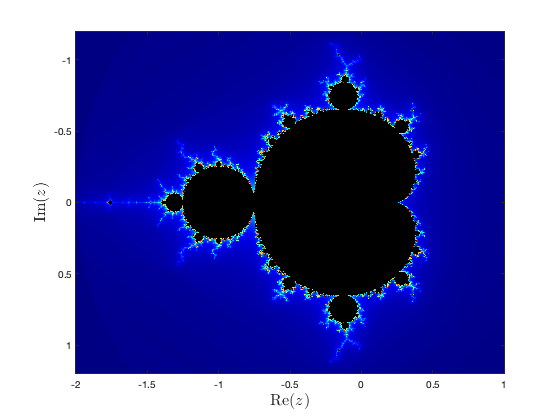


% Plot Mandelbrot set
imagesc(x, y, img(end:-1:1,:))
axis equal tight
xlabel('Re$(z)$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('Im$(z)$', 'Interpreter', 'latex', 'FontSize', 16)

We can explore the Mandelbrot set by changing the values of `xmin`, `xmax`, `ymin`, `ymax` and `maxiter` and calling the `mandelbrot_set` function again to regenerate the `img` array. Uncomment/comment the lines below to see the results.

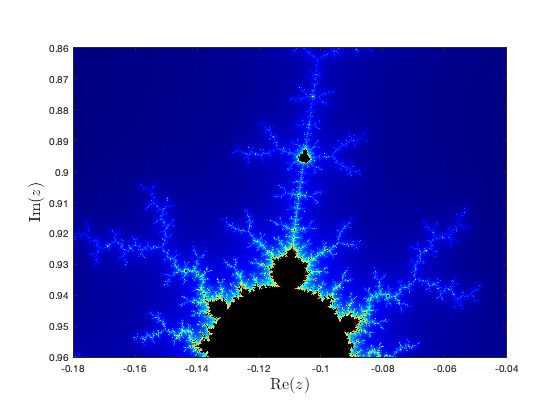

% Define real and imaginary values
xmin = -0.18; xmax = -0.04; ymin = 0.86; ymax = 0.96;
% xmin = -0.8; xmax = -0.77; ymin = 0.135; ymax = 0.155;
% xmin = -0.134; xmax = -0.124; ymin = 0.984; ymax = 0.992;
% xmin = -0.749; xmax = -0.747; ymin = 0.1225; ymax = 0.124;
maxiter = 200;

% Generate Mandelbrot set
x = linspace(xmin, xmax, width);
y = linspace(ymin, ymax, height);
img = mandelbrot_set(x, y, maxiter);

% Plot Mandelbrot set
imagesc(x, y, img(end:-1:1,:))
axis equal tight
xlabel('Re$(z)$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('Im$(z)$', 'Interpreter', 'latex', 'FontSize', 16)

## Solving a system of ODEs

The well known [SIRD model](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRD_model) is a system of 4 Ordinary Differential Equations (ODEs) that model the dynamics of an epidemic, e.g., the flu.


$$\frac{dS}{dt} = -\frac{\beta I S}{N}, \\
\frac{dI}{dt} = \frac{\beta I S}{N} - \gamma I - \mu I, \\
\frac{dR}{dt} = \gamma I, \\
\frac{dD}{dt} = \mu I.$$


where $S$ is the number of people susceptible to the virus, $I$is the number of people infected, $R$ is the number of people who have recovered, $D$ is the number of people who have died and $N= S+I+R+D$ is the total number of people in the population. The model parameters are $\beta$, $\gamma$ and $\mu$ which are the rates of infection, recovery and mortality respectively.

The program below solves the SIRD system for the initial value problem $S(0)=999$, $I(0)=1$, $R(0)=D(0)=0$ with $\beta=0.3$, $\gamma = 0.05$ and $\mu=0.01$ using a Runge-Kutta method.

% Define IVP
y0 = [999, 1, 0, 0];
tspan = [0, 100];
beta = 0.3;
gamma = 0.05;
mu = 0.01;

% Solve IVP (using 4/5th order Runge-Kutta method)
[t, y] = ode45(@(t, y)SIRD_model(t, y, beta, gamma, mu), tspan, y0);

% Plot solution
plot(t, y)
axis([tspan, 0, 1100])
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('population', 'Interpreter', 'latex', 'FontSize', 16)
legend('Susceptible', 'Infected', 'Recovered', 'Deceased', ...
    'Interpreter', 'latex', 'FontSize', 12)

## Functions

The function below generates the Mandelbrot set for real and imaginary values $x$ and $y$ and ceasing iterations when `maxiter` is reached. This function makes use of **array masking** where the array `i`  is the same size as the `img` array that contain boolean values `true` or `false` which are then used to index the arrays `X`, `Y`, and `img`.

function img = mandelbrot_set(x, y, maxiter)

% This function generates an image array containing the Mandelbrot set for
% the real and imaginary values stored in x and y.

% Initialise pixel arrays
height = length(y);         % size of image array
width = length(x);
img = zeros(height, width); % image array
[X0, Y0] = meshgrid(x, y);  % starting values of x and y
X = zeros(size(X0));        % current values of x
Y = zeros(size(X0));        % current values of y
Xold = zeros(size(X0));     % values of x from previous iteration 

% Iteration loop
for n = 1 : maxiter
    
    % Determine pixels that are still inside of the Mandelbrot set 
    % (|x + iy| < 2)
    i = X .^ 2 + Y .^ 2 < 4;
    
    % Calculate new values of X and Y
    X(i) = X(i) .^ 2 - Y(i) .^ 2 + X0(i);
    Y(i) = 2 * Xold(i) .* Y(i) + Y0(i);
    Xold = X;

    % Increment those points inside the Mandelbrot set by 1.
    img(i) = img(i) + 1;
    
    % Apply normalised iteration count to those points who have left the
    % Mandelbrot set in the current iteration
    i = img == n - 1;
    img(i) = n + 1 - log(log(X(i) .^ 2 + Y(i) .^ 2) / log(2)) / log(2);
    
end

end

The SIRD function is defined below.

function dydt = SIRD_model(~, y, beta, gamma, mu)

% This function defines the SIRD system of ODEs

% Unpack y array
S = y(1);
I = y(2);
N = sum(y);

% Define SIRD system
dydt = zeros(4, 1);
dydt(1) = -beta * I * S / N;
dydt(2) = beta * I * S / N - gamma * I - mu * I;
dydt(3) = gamma * I;
dydt(4) = mu * I;

end
